% Parameters
fs = 11e6;  % Sampling frequency (11 MHz)
fc = 2.4e9; % Carrier frequency (2.4 GHz)
t = 0:1/fs:1; % Time vector

% Generate binary data
%data = randi([0, 1], 1, 10000);
%data = [[1,1,1,0,0],randi([1], 1, 9995)];
%data = [[0,1,1,0,0],zeros(1,9995)];
%symbols = 2 * data - 1;


load('80211data.mat');
data = modSig.';
% Barker Sequence data
barker = [1; -1; 1; 1; -1; 1; 1; 1; -1; -1; -1];
inv_barker = barker * -1;
symbols = [];
vectorLength = length(modSig);
for i = 1:vectorLength
    if modSig(i)==1
        symbols = [symbols; barker];
    else
        symbols = [symbols; inv_barker];
    end
end



carrier = 1;

% 1 bit is positive voltage, 0 bit is negative voltage
data_to_voltage = zeros(1,length(data));
for i = 1:numel(data)
    carrier = carrier * -1; % 
    if data(i) == 0
        carrier = carrier * -1;
    end
    data_to_voltage(i) = carrier;
end

actual = data_to_voltage;

% IQ MODULATE: I & Q MIXERS TIED TOGETHER
% Loop through each element in the array
for i = 1:numel(actual)
    % Check if the number is positive or negative and modify accordingly
    if actual(i) > 0
        actual(i) = actual(i) + 1i;
    elseif actual(i) < 0
        actual(i) = actual(i) - 1i;
    end
end

actual = actual.';
%constDiagram = comm.ConstellationDiagram;
%constDiagram(actual);



dbpskdemod = comm.DBPSKDemodulator();
%demod_data = dbpskdemod(iq_modulated.').';
dbpskdemod = comm.DBPSKDemodulator();
demod_data_actual = dbpskdemod(actual).';

disp('Original data:')

Original data:


disp(data(1,1:10))

     0     1     1     1     1     1     1     0     1     1



%disp(demod_data(1,1:10));
disp('Modulated and demodulated data:')

Modulated and demodulated data:


disp(demod_data_actual(1,1:10))

     0     1     1     1     1     1     1     0     1     1





%scatterplot(complex(symbols, symbols));
%title('Constellation Diagram');
%constDiagram = comm.ConstellationDiagram;
%constDiagram(iq_modulated.')



## modulate onto wave

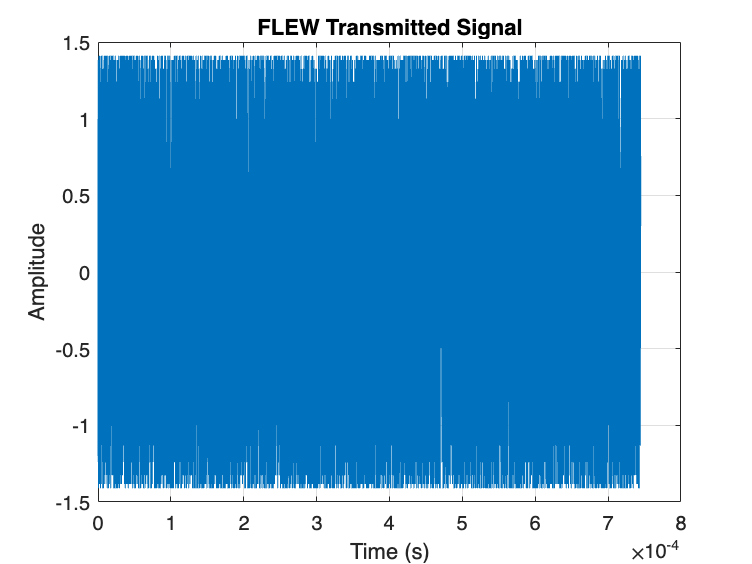

carrierFrequency = 2.412e9; % Carrier frequency in Hz (2.414 GHz)
symbolRate = 11e6; % Symbol rate in Hz (11 MHz)

t = 0:1/symbolRate:(length(actual)-1)/symbolRate;

carrier = cos(2 * pi * carrierFrequency * t);

% Create the I and Q components by splitting the modulated symbols
I = real(actual);
Q = imag(actual);

% Modulate the I and Q components onto the carrier wave
modulatedSignal = I .* carrier' + Q .* sin(2 * pi * carrierFrequency * t)';


% Plot the modulated signal
figure;
plot(t, modulatedSignal);
title('FLEW Transmitted Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;